P=[[0;0],[0.5;-1],[1;0],[0.5;1],[0;0],[-0.5;-1],[-1;0],[-0.5;1],[0;0]]

P =                    0   0.500000000000000   1.000000000000000   0.500000000000000                   0  -0.500000000000000  -1.000000000000000  -0.500000000000000                   0
                   0  -1.000000000000000                   0   1.000000000000000                   0  -1.000000000000000                   0   1.000000000000000                   0


n=length(P)-1

n =      8


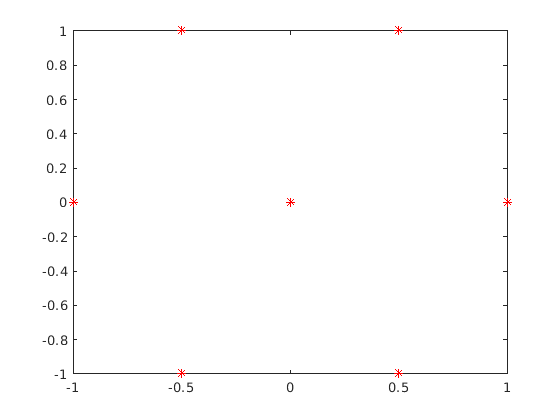

p=2;
k=n+1-p;
plot(P(1,:),P(2,:),'r*')

T=[0,0,0,1,2,3,4,5,6,7,7,7];
T=T/k % interval [0,1] is used for parameters;

T =                    0                   0                   0   0.142857142857143   0.285714285714286   0.428571428571429   0.571428571428571   0.714285714285714   0.857142857142857   1.000000000000000   1.000000000000000   1.000000000000000


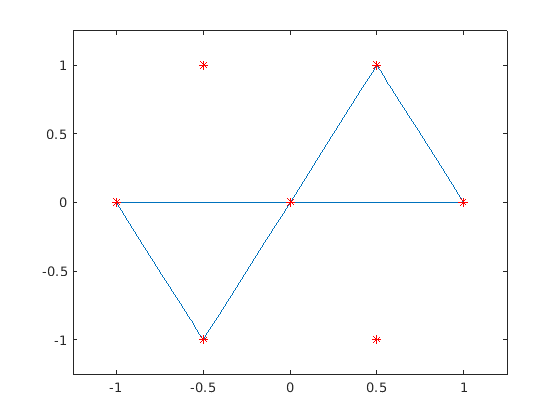

tt=linspace(0,1,101);
W=[1,0,1,100,1,100,1,0,1];
[X,Y]=nurbs(T,P,W,p,tt);
plot(X,Y,P(1,:),P(2,:),'r*')
axis([-1.25 1.25 -1.25 1.25]);